# L6 - Exercici 2

clear all; close all; format long


La ecuación $$e^x= \beta x^2-1$$ tiene una raíz en el intervalo [−4,0] para $$0.1 < \beta < 1$$  

**a)** Valor de $$\beta$$. En el live script de MATLAB® obten un valor aleatorio uniforme en el intervalo [0.1,1] para el parámetro $$\beta$$ (dos cifras significativas). Consulta la documentación de [rand](https://es.mathworks.com/help/matlab/ref/rand.html) y la documentación de [round](https://es.mathworks.com/help/matlab/ref/round.html).

beta = round(0.1 + (1-0.1)*rand(1,1),2)

beta =    0.350000000000000


**Respuesta** $$\beta$$ = 

**b)** Comprobad que la ecuación $$e^x= \beta x^2-1$$ tiene una solución real en el intervalo [−4,0].  Determinad un intervalo [a,b] de longitud b−a = 0.1, que contenga la solución.

% comprovacion de la solucion

f = @(x) - exp(x) + beta*x.^2 - 1

f = function_handle with value:
    @(x)-exp(x)+beta*x.^2-1


a = -4; b = 0;

% comprovamos que la equacion tiene una solucion real en el intervalo
f(a)*f(b) < 0   % cierto

ans = logical
   1



% busquem el interval de tamany 0.1 en que hi ha el canvi de signe
while f(a)*f(a+0.1) > 0
    a = a+0.1;
end

I = [a, a+0.1] % interval on est troba la solucio

I =   -1.899999999999998  -1.799999999999998


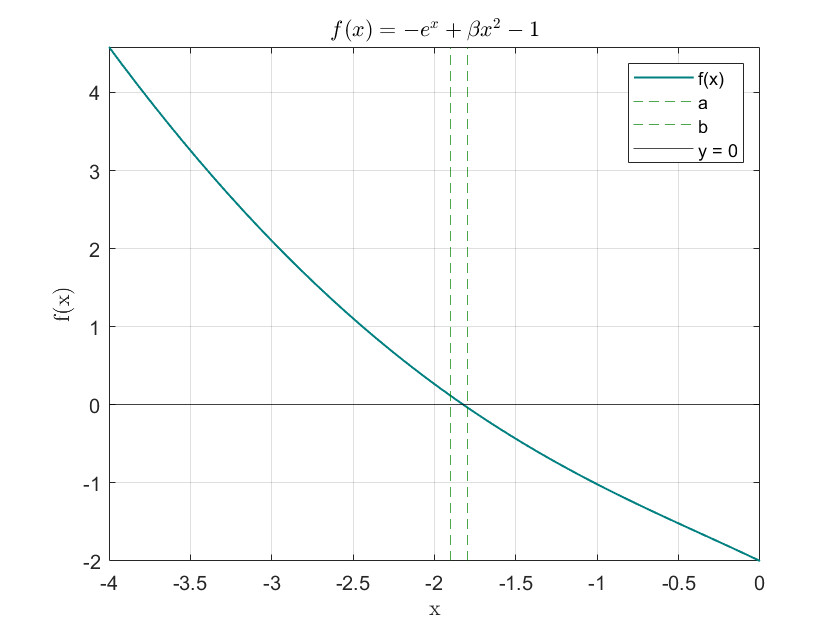


% represnetacio gràfica de la funció, i l'interval on es troba la solució
fplot(f, [-4 0], 'LineWidth',1, 'Color',[0 0.5 0.5])
title('$f(x)= - e^x + \beta x^2-1$', 'Interpreter',"latex")
xlabel('x', "Interpreter","latex")
ylabel('f(x)','Interpreter',"latex")
xline(a, '--', 'Color', [0 0.5 0])
xline(a+0.1, '--','Color', [0 0.5 0])
yline(0, 'k')
grid on
legend('f(x)', 'a', 'b', 'y = 0')

**Respuesta** Gráfica, tabla de valores y intervalo [a,b].

**c)** Construid el método iterativo 


$$$x_{n+1}=x_n-\lambda \cdot f(x_n)$$$


para determinar la solución aproximada de la ecuación $$e^x= \beta x^2-1$$ por el método del punto fijo  en el intervalo $$ [a,a+0.1]$$

**caso 1) **Tomar  $$x_0=a$$,$$\lambda =\frac{1}{2f\prime (x_0)}$$ y obtener, con 8 decimales de exactitud, la aproximación $$x_n \approx  \alpha$$

xn1 = [a+0.1 a]; % posem els dos per poder fer la comprovacio inicial del bucle
h = 10e-6;
dx = (f(a+h)- f(a))/h;
lambda = 1/(2*dx)

lambda =   -0.337936965922746


while abs(xn1(end-1)-xn1(end)) > 10e-8
    xnext = xn1(end) - lambda*f(xn1(end));
    xn1 = [xn1 xnext];
end

xn1             % succecio d'aproximacions

xn1 =   -1.799999999999998  -1.899999999999998  -1.861498374856707  -1.842110214431761  -1.832243511384414  -1.827195875936120  -1.824606720985922  -1.823276827479368  -1.822593266518023  -1.822241793154910  -1.822061039491846  -1.821968073805569  -1.821920257141476  -1.821895662149732  -1.821883011301416  -1.821876504081619  -1.821873156950117  -1.821871435276474  -1.821870549693464  -1.821870094172970  -1.821869859865211  -1.821869739343450  -1.821869677350215


fxn1 = f(xn1)   % succecio de valors

fxn1 =   -0.031298888221589   0.113931380777362   0.057372120780000   0.029196874098711   0.014936618237404   0.007661650577726   0.003935330078267   0.002022746932934   0.001040055982493   0.000534873900433   0.000275097712449   0.000141495808137   0.000072779820570   0.000037435526718   0.000019255720602   0.000009904603046   0.000005094659113   0.000002620556788   0.000001347945150   0.000000693347523   0.000000356639769   0.000000183446148   0.000000094359893


**Respuesta** Sucesión de aproximaciones $$x_n$$ y sucesión de valores $$f(x_n)$$.

**caso 2) **Tomar  $$x_0=a$$, $$\lambda =\frac{1}{f\prime (x_0)}$$ y obtener, con 8 decimales de exactitud, la aproximación $$x_n \approx  \alpha$$.

xn2 = [a+0.1 a];
lambda2 = 1/(dx)

lambda2 =   -0.675873931845491


while abs(xn2(end-1)-xn2(end)) > 10e-8
    xnext = xn2(end) - lambda2*f(xn2(end));
    xn2 = [xn2 xnext];
end

xn2             % succecio d'aproximacions

xn2 =   -1.799999999999998  -1.899999999999998  -1.822996749713417  -1.821901783124092  -1.821870536351854  -1.821869638268941  -1.821869612451329


fxn2 = f(xn2)   % succecio de valors

fxn2 =   -0.031298888221589   0.113931380777362   0.001620075191145   0.000046231657660   0.000001328772824   0.000000038198856   0.000000001098127


**Respuesta** Sucesión de aproximaciones $$x_n$$ y sucesión de valores $$f(x_n)$$.

**caso 3) **Tomar   $$x_0=a$$, $$\lambda =\frac{2}{f\prime (x_0)}$$  y obtener, con 8 decimales de exactitud, la aproximación $$x_n \approx \alpha$$

xn3 = [a+0.1 a];
lambda3 = 2/(dx)

lambda3 =   -1.351747863690982


while abs(xn3(end-1)-xn3(end)) > 10e-8
    xnext = xn3(end) - lambda3*f(xn3(end));
    xn3 = [xn3 xnext];
end

xn3             % succecio d'aproximacions

xn3 =   -1.799999999999998  -1.899999999999998  -1.745993499426835  -1.891304921934097  -1.754660505529814  -1.883582419787830  -1.762311016710724  -1.876721174932611  -1.769071238442365  -1.870623587516318  -1.775049836390747  -1.865203755410084  -1.780340868996430  -1.860385848986844  -1.785026106103474  -1.856102780532684  -1.789176889967486  -1.852295097292122  -1.792855649460097  -1.848910047647616  -1.796117147235227  -1.845900783991870  -1.799009518129512  -1.843225675584618  -1.801575141990814  -1.840847711487394  -1.803851383413682  -1.838733978469355  -1.805871223150844  -1.836855202200245  -1.807663800353758  -1.835185342517169  -1.809254880653796  -1.833701235359865  -1.810667262003791  -1.832382275312985  -1.811921127862398  -1.831210133710467  -1.813034355514834  -1.830168508040682  -1.814022785937068  -1.829242899007261  -1.814900460522758  -1.828420412094799  -1.815679829128338  -1.827689580892794  -1.816371933197744  -1.827040209767599  -1.816986567164591  -1.826463233

fxn3 = f(xn3)   % succecio de valors

fxn3 =   -0.031298888221589   0.113931380777362  -0.107498910418460   0.101087207218639  -0.095374231926649   0.089714514322198  -0.084638682475507   0.079637585811532  -0.075126694705225   0.070703829976550  -0.066694330681737   0.062780115059279  -0.059215910112001   0.055749851660648  -0.052581310715101   0.049510631651716  -0.046693772574044   0.043972289084833  -0.041468087128661   0.039055286736860  -0.036829084841834   0.034689358216790  -0.032710358671752   0.030812353925292  -0.029053176669608   0.027369252112367  -0.025805548499574   0.024311305533547  -0.022921418913730   0.021595300891972  -0.020359967197036   0.019182913145185  -0.018084995998675   0.017040140380307  -0.016064396247611   0.015136807684473  -0.014269677331244   0.013446130512834  -0.012675553619196   0.011944329661840  -0.011259579895791   0.010610291216100  -0.010001829435206   0.009425265841865  -0.008884609391327   0.008372602612551  -0.007892208936602   0.007437513217558  -0.007010676211533   0.00660686

**Respuesta** Sucesión de aproximaciones $$x_n$$ y sucesión de valores $$f(x_n)$$.

**d)** Calcular para cada método convergente, $$x_n$$ los valores

                                                
$$$r_{n+1}=-log_{10}(2\frac{|x_{n+1}-x_n|}{|x_{n+1}|)$$$


(aproximación de las cifras significativas) de cada método iterativo convergente.

close all
% para el metodo 1 
d1 = diff(xn1);
rn1 = -log10(2.*d1./xn1(2:end))

rn1 =   0.977723605288847 + 0.000000000000000i  1.383353604389412 - 1.364376353841841i  1.676749010461728 - 1.364376353841841i  1.967781139034671 - 1.364376353841841i  2.257667129046512 - 1.364376353841841i  2.546981232663557 - 1.364376353841841i  2.836005751272905 - 1.364376353841841i  3.124882513907874 - 1.364376353841841i  3.413683590299941 - 1.364376353841841i  3.702445818937285 - 1.364376353841841i  3.991188087307462 - 1.364376353841841i  4.279920094454813 - 1.364376353841841i  4.568646825037662 - 1.364376353841841i  4.857370841891824 - 1.364376353841841i  5.146093463006904 - 1.364376353841841i  5.434815366196346 - 1.364376353841841i  5.723536900098350 - 1.364376353841841i  6.012258244044533 - 1.364376353841841i  6.300979490345761 - 1.364376353841841i  6.589700686455822 - 1.364376353841841i  6.878421856365105 - 1.364376353841841i  7.167143013817223 - 1.364376353841841i



% para el metodo 2
d2 = diff(xn2);
rn2 = -log10(2.*d2./xn2(2:end))

rn2 =   0.977723605288847 + 0.000000000000000i  1.073246841659206 - 1.364376353841841i  2.920094097462755 - 1.364376353841841i  4.464682354943846 - 1.364376353841841i  6.006170869039407 - 1.364376353841841i  7.547571240910449 - 1.364376353841841i



% Podem veure que el metode 3 no és convergent, degut al altisim nombre d'iteracions que requereix 
d3 = diff(xn3);
rn3 = -log10(2.*d3./xn3(2:end))

rn3 =   0.977723605288847 + 0.000000000000000i  0.753473574093503 - 1.364376353841841i  0.813431802840844 + 0.000000000000000i  0.807571215137581 - 1.364376353841841i  0.863627887306873 + 0.000000000000000i  0.861294158199463 - 1.364376353841841i  0.913905172275439 + 0.000000000000000i  0.914701548191030 - 1.364376353841841i  0.964266436782909 + 0.000000000000000i  0.967841923425966 - 1.364376353841841i  1.014711675142839 + 0.000000000000000i  1.020755366632862 - 1.364376353841841i  1.065238931337420 + 0.000000000000000i  1.073475168374108 - 1.364376353841841i  1.115844926048105 + 0.000000000000000i  1.126029125337123 - 1.364376353841841i  1.166525525961698 + 0.000000000000000i  1.178440562029696 - 1.364376353841841i  1.217276092658220 + 0.000000000000000i  1.230729140807123 - 1.364376353841841i  1.268091739413500 + 0.000000000000000i  1.282911508457079 - 1.364376353841841i  1.318967517601466 + 0.000000000000000i  1.335001815566391 - 1.364376353841841i  1.369898549382787 + 0.0000000000



semilogx(1:length(rn1), rn1)

hold on
semilogx(1:length(rn2), rn2)

semilogx(1:length(rn3), rn3)

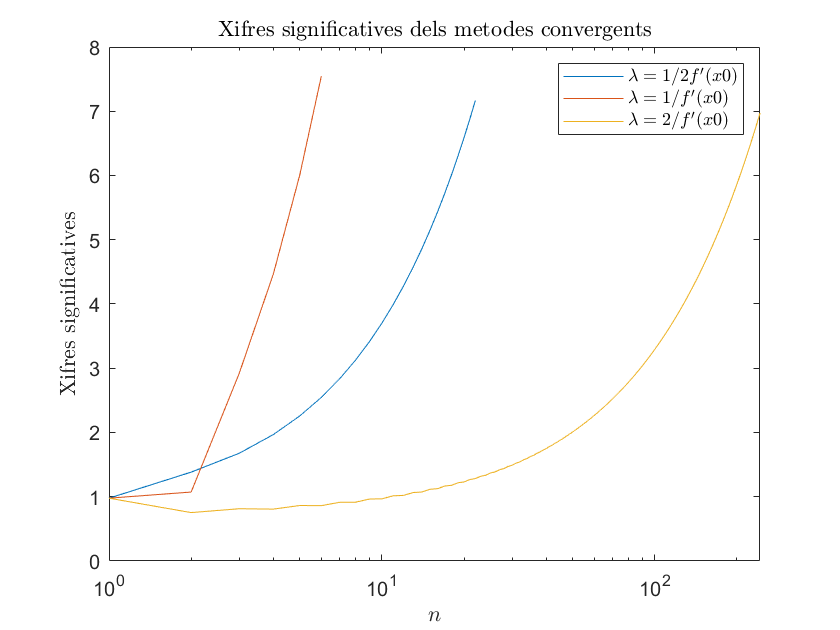


legend("$\lambda = 1/2f'(x0)$", "$\lambda = 1/f'(x0)$", "$\lambda = 2/f'(x0)$",'Interpreter',"latex")
title('Xifres significatives dels metodes convergents', 'Interpreter',"latex")
xlabel('$n$', 'Interpreter',"latex")
ylabel('Xifres significatives', 'Interpreter',"latex")

**Respuesta** Gráfico los valores $$r_n$$ debidamente rotulado. 

**e)** De los tres métodos analizados, ¿cuál sería el mejor procedimiento, más eficiente, para obtener la raíz de  $$e^x= \beta x^2-1$$? ¿Podrías encontrar un valor de $$\lambda$$  que minimice el número de iterados a calcular?

% Dels tres mètodes, el que és notablement pitjor és el tercer (lambda = 2/f'(x0)), 
% per això, el descartem ja que no convergeix. En els altres dos mètodes, la 
% diferència la trobem en la velocitat de convergència, és a dir, com de ràpid 
% ens apropem a les 8 xifres significatives correctes. És per això que el mètode
% 2 seria el millor procediment dels tres, en base a la gràfica obtinguda  a 
% l'apartat anterior.  

% Per a trobar el valor mínim de lambda, ho farem de forma analítica.


Si definim $$g(x)=x-\lambda \cdot f(x)$$ llavors $$g'(x)=1-\lambda \cdot f'(x)$$, que es mínim quan $$g'(x) = 0$$, és a dir, quan $$0=1-\lambda \cdot f'(x)$$ que implica $$\lambda = \frac{1}{f'(x)}$$ . Per tant, el valor òptim de $$\lambda$$ és aquell que ja haviem usat en el mètode 2. 